# Properties

resolution = 0.005;
wavelength = 1;
amplitude = 1;
xh = -1:resolution:1;
fsize = 16;

## Define Waves

g = geometry(resolution);
testph = height_error(g,{'Z','Z_20'},g.circa);
%testph.plot_height(g);
testph = testph.zernike_coefficients(g);
testph.c_nm;
t = wave(wavelength,testph.distribution,amplitude,g); %test wave definition
refph = height_error(g,{'T',2,2},1);
r = wave(wavelength,refph.distribution,amplitude,g); %reference wave definition

## Error Analysis

%{
fsize = 16
alpha = linspace(0,1,100);
alpha_lnp = detector_error(alpha, 1,0.1);
alpha_lnn = detector_error(alpha, 1,-0.1);
alpha_2p = detector_error(alpha, 2,0.1);
alpha_2n = detector_error(alpha, 2,-0.1);


figure()
plot(alpha,alpha_lnp,'r');
xlabel('Incoming Intensity')
ylim([0 1])
ylabel('Detected Signal')
set(gca,'fontsize', fsize);
set(gca, 'FontName', 'Times New Roman')
legend('Location','northwest')
hold on
plot(alpha,alpha,'k.');
plot(alpha,alpha_lnn,'b--');
legend([char(949),'=0.1'],[char(949),'=0'],[char(949),'=-0.1'])
hold off

figure()
plot(alpha,alpha_2p,'r');
ylim([0 1])
set(gca,'fontsize', fsize);
set(gca, 'FontName', 'Times New Roman')
xlabel('Incoming Intensity')
ylabel('Detected Sigmal')
legend('Location','northwest')
hold on
plot(alpha,alpha,'k.');
plot(alpha,alpha_2n,'b--');
legend([char(949),'=0.1'],[char(949),'=0'],[char(949),'=-0.1'])
hold off

alpha_po = detector_error(alpha, 'p',0.1);
alpha_gu = detector_error(alpha, 'g',0.5);
alpha_go = detector_error(alpha, 'g',2);
figure()
plot(alpha,alpha_po,'r');
ylim([0 1])
set(gca,'fontsize', fsize);
set(gca, 'FontName', 'Times New Roman')
legend('Location','southeast')
xlabel('Incoming Intensity')
ylabel('Detected Sigmal')
hold on
plot(alpha,alpha,'k.');
plot(alpha,alpha_gu,'b--');
plot(alpha,alpha_go,'gx');
legend(['Poisson Noise'],['No Noise'],['\gamma =0.2'],['\gamma =5'])
hold off
%}

## Testing Algorithms

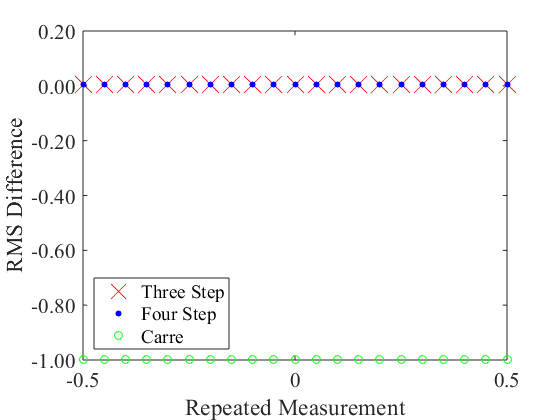

n_p = 1;
epsilon_p = 0;
n_I = 0;
epsilon_I = 0;
org_dist = g.circa.*testph.distribution/nansum(g.circa.*testph.distribution,'all');
eps_lst = linspace(-0.5,0.5,21);
three = [];
four = [];
ave3 = [];
carre = [];
for i=eps_lst
    sp_3 = PSI(t,r,3,g,'centre',n_p,i,n_I,i);
    sp_3.c_nm;
    sigma_3 = sum(cell2mat(sp_3.c_nm(:,2))) - sum(cell2mat(testph.c_nm(:,2)));  
    %sigma_3 = nansum(sp_3.phase./nansum(sp_3.phase,'all') - org_dist,'all');
    sp_4 = PSI(t,r,4,g,'centre',n_p,i,n_I,i);
    
    sigma_4 = sum(cell2mat(sp_4.c_nm(:,2))) - sum(cell2mat(testph.c_nm(:,2))); 
    %sigma_4 = nansum(sp_4.phase./nansum(sp_4.phase,"all") - org_dist,"all");
    
    %sp_2 = PSI(t,r,2,g,'centre',n_p,i,n_I,epsilon_I); %ave
    %sigma_2 = sum(cell2mat(sp_2.c_nm(:,2))) - sum(cell2mat(testph.c_nm(:,2))); %nansum(sp_2.phase./nansum(sp_2.phase,"all") - org_dist,"all");
    sp_1 = PSI(t,r,1,g,'centre',n_p,i,n_I,epsilon_I); %carre
    sigma_1 = sum(cell2mat(sp_1.c_nm(:,2))) - sum(cell2mat(testph.c_nm(:,2)));
    %sigma_1 = nansum(sp_1.phase./nansum(sp_1.phase,"all") - org_dist,"all");
    three = [three,sigma_3];
    four = [four,sigma_4];
    %ave3 = [ave3,sigma_2];
    carre = [carre,sigma_1];
end

figure()
plot(eps_lst,three,'rx','MarkerSize',fsize);
ytickformat('%,.2f')
set(gca,'fontsize', fsize);
set(gca, 'FontName', 'Times New Roman')
%set(gca,'xtick',[])
%set(gca,'xticklabel',[])
xlabel('Repeated Measurement')
ylabel('RMS Difference')
legend('Location','southwest')
hold on
plot(eps_lst,four,'b.','MarkerSize',fsize);
%plot(eps_lst,ave3,'kv');
plot(eps_lst,carre,'go');
legend('Three Step','Four Step', 'Carre')%,'Average 3')%,'Carre')
hold off

## Superposition



%sp_real = PSI(t,r,0,g,'centre',100,1,0);
%sp_pure = PSI(t,r,3,g,'centre',1,1,0);
%imshow(sp_pure.Int,[])

%figure()
%subplot(1,2,1)
%imshow(sp_4.wrap,[])
%sp_real.plot_interference(g);
%title('Real')
%subplot(1,2,2)
%imshow(sp_pure.Int,[])
%sp_pure.plot_interference(g);
%title('Perfect')
%sp_real.c_nm
%sp_pure.c_nm

%figure()
%subplot(1,2,1)
%imshow(sp_1.wrap,[])
%title('Real Wrap')
%subplot(1,2,2)
%imshow(sp_pure.wrap,[])
%title('Perfect Wrap')

%figure()
%subplot(1,3,1)
%imshow(sp_real.phase,[])
%title('Real Phase')
%subplot(1,3,2)
%imshow(sp_pure.phase,[])
%title('Perfect Phase')
%subplot(1,3,3)
%imshow(g.circa.*testph.distribution,[])
%title('Original Phase')
